# 画像をExcelにするMATLAB術

## はじめに

こんにちは、HerniaBabyです。

皆さんExcel大好きですよね？世間では[ネ申Excel](https://qiita.com/e99h2121/items/ef194c4fec579ec2c11c)といわれるものが世の中にはびこるくらい日本人はExcel大好きだと思っています。

もはやExcelは和の心、大和魂…。

そんなわけで今回は[画像を別の形式に変換するクソアプリ](https://qiita.com/de_teiu_tkg/items/f71e06e8cf7343453f2e)をMATLABでやっていきたいと思います。

## 画像を読み込む

まずは画像を読み込みましょう。

このときに方眼に色を書き込むんですが、画像がデカいと反映されないみたいなので[imresize](https://jp.mathworks.com/help/matlab/ref/imresize.html)で小さくしていきます。

色の制限もあるっぽいですが、今回はめんどくさいので減色もしません。

:::note warn

反映されない理由

[Excel で「異なるセル形式が多すぎます」というエラー メッセージが表示される](https://learn.microsoft.com/ja-JP/office/troubleshoot/excel/too-many-different-cell-formats-in-excel)

:::

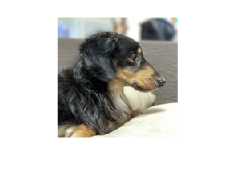

clc, close all, clear;
I = imread('chacha_sq.jpeg');
I = imresize(I,[150 150]);
imshow(I)

画像は愛犬チャチャです。かわいいね( *´艸｀)

行番号と列番号を抽出します。

[row, col]  = size(I,1,2);

## 列番号をExcelに対応させる

Excelは列がA...AA...AAAのような英語になっています。

列番号をこれに対応させる必要があります。

[MATLABで数字をExcelの列名に変換](https://qiita.com/hibs_MATLAB_Amb/items/edf096d73cdf671ddd8a)でMATLABアンバサダーの方が紹介してくれてますが、今回はMATLAB Answersのものを拾って使ってます。

[I need to convert a number into its column name equivalent](https://jp.mathworks.com/matlabcentral/answers/248797-i-need-to-convert-a-number-into-its-column-name-equivalent#answer_405713)

col_e       = arrayfun(@int2xlcol, (1:col));
ImgString   = col_e + string((1:row)');

## 背景色番号を抽出

RGB値を抜き出してExcelで使えるようにします。

最初は [Cody](https://jp.mathworks.com/matlabcentral/cody/groups/62/problems/1948) を参考にHex Stringに直してたんですが、結局[hex2dec](https://jp.mathworks.com/help/matlab/ref/hex2dec.html)に直してたのでそのままdouble型で出してます。

:::note warn

[How to set excel cell color to red from Matlab?](https://jp.mathworks.com/matlabcentral/answers/3352-how-to-set-excel-cell-color-to-red-from-matlab#answer_240369)

ExcelはBGRなので注意してください。

:::

I_d         = im2double(I);
[R,G,B]     = imsplit(I_d);
bgrColor    = (B.*256^2 + G.*256 + R).*255;

## Cell型に変換

forループを使うとMATLABフリークスがマジギレするので[cellfun](https://jp.mathworks.com/help/matlab/ref/cellfun.html)を使います。

そのためcell配列に変換します。

ImgCells        = cellstr(ImgString);
bgrColorCell    = num2cell(bgrColor);

## MATLABからExcelを操作しよう

こいつのドキュメント本当に少なくて苦労しました。

**MathWorksさん！Excelは大和魂ぞ？！充実させてください(白目)**

今回は色んなところからかき集めたので説明していきます。

まずはパスを指定します。

%Obtain the full path name of the file
filePath = fullfile(pwd, 'Book1.xlsx');

ExcelをActiveXで起動させます。

%Open an ActiveX connection to Excel
h = actxserver('excel.application');

Excelファイルを開きます。

%Open an excel file
wb = h.Workbooks.Open(filePath,0,false);

ここで各セルに背景色を書き込みます。

cellfun(@(x,y) xlscolor(h, x, y), ImgCells, bgrColorCell)

行の高さと列の幅を正方形にします。

ハンドルプロパティどこあるのか苦労しました。

列幅はQiita([【MATLAB】Excel ファイルのセル幅自動調整](https://qiita.com/eigs/items/3a71c0da1744e48e9bca))にあったんですよね。高さが…。

ちなみに正方形の調整は以下を参考にしました。

[Excelの技：すべてのセルを正方形にして方眼紙のように！](https://xtech.nikkei.com/it/pc/article/knowhow/20090219/1012449/)

range = ImgString(1)+":"+ImgString(end);
wbrange = wb.ActiveSheet.get('Range',range);
wbrange.EntireColumn.ColumnWidth = 1.88;
wbrange.EntireRow.RowHeight = 15;

最後に上書き保存してExcelを閉じます。

% save the file with the given file name, close Excel
wb.Save;
wb.Close;
h.Quit;
h.delete;
disp('完了')

完了


## 使用した関数

### 数字をExcelの列に対応する関数

function str = int2xlcol(num)    
    raw = 'A':'Z';
    str = raw(1+rem(num-1,26));
    tmp = fix((num-1)/26);
    while any(tmp)
        str = [raw(1+rem(tmp-1,26)),str];
        tmp = fix((tmp-1)/26);
    end
    str = string(str);
end

### 背景を塗りつぶす関数

function xlscolor(h, range, Color)
    ran = h.Activesheet.get('Range',range);
    ran.interior.Color = Color;
end

## 結果

けっこうよくないですか？！

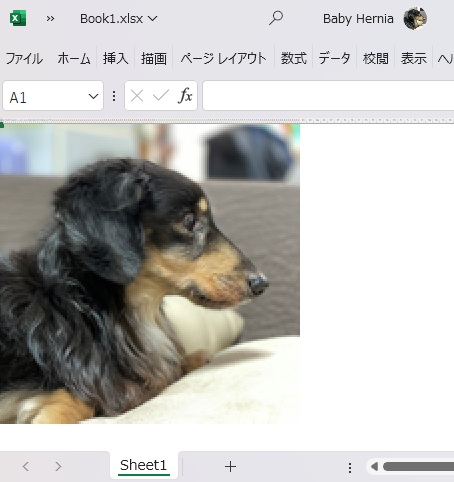

アップするとこんな感じです！

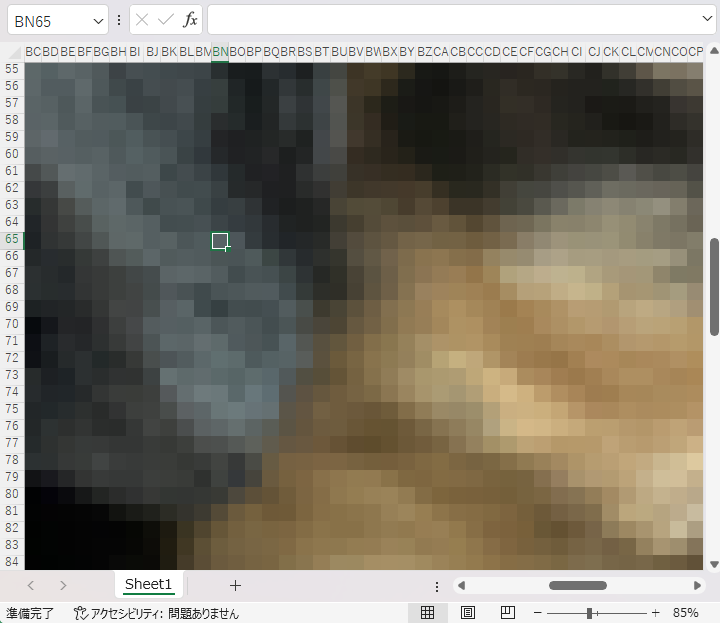

てことで完成です。

## おわりに

今回は業務に関連するものではなく気ままに作りました。

応用すると昔流行った[ExcelでBadApple](https://youtube.com/shorts/-2mYZpqF2VE?si=xWCxYa60Mb8l-x7S)なんかも出来そうですね。

cellfun使ったんですがやり方が悪いのか計算が遅いんですよね。

誰か列指定して一気に背景色反映させる方法知りません？

知ってたら教えてください。